clear
clear image

% Path for Q2 image
ImagePath = 'https://i.ibb.co/cCt7Rx7/Q2-image.jpg';

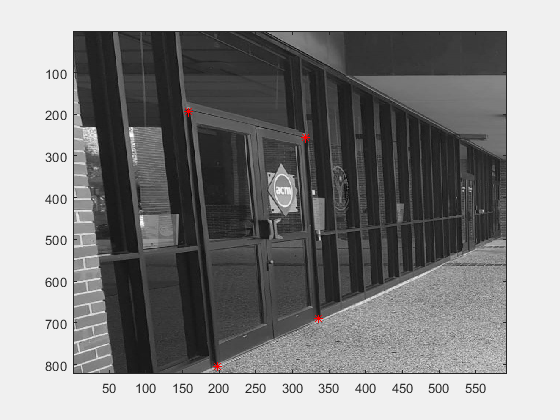

  158.0484
  193.4184



  317.6429
  255.7274



  197.6060
  804.5262



  335.3756
  689.4942




% selecting points on gray scale image 
pointsOnImage = [];
[Img, Col]= imread(ImagePath);
gsimage = rgb2gray(Img);
image(gsimage); drawnow; hold on;
colormap(gray(256))
for i=1:4
[x, y]=ginput(1);
v=[x;y];
disp(v);
plot(x, y, 'r*');
pointsOnImage=[pointsOnImage v];
end

disp(pointsOnImage);

  158.0484  317.6429  197.6060  335.3756
  193.4184  255.7274  804.5262  689.4942



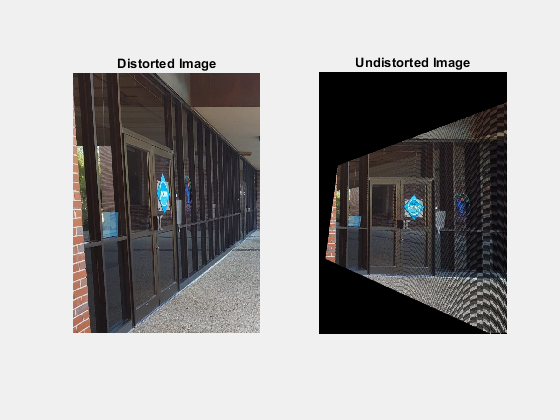


[rows,cols,~] = size(gsimage);
newImage = zeros(rows,cols);

% choosing points on new image 
newImagePoints = [160 360 160 360; 340 340 640 640;1 1 1 1];

M = [];
for j=1:4    
   r1 = [0 0 0  -newImagePoints(1,j) -newImagePoints(2,j) -newImagePoints(3,j) pointsOnImage(2,j)*newImagePoints(1,j) pointsOnImage(2,j)*newImagePoints(2,j) pointsOnImage(2,j)*newImagePoints(3,j)]; 
   r2 = [newImagePoints(1,j) newImagePoints(2,j) newImagePoints(3,j) 0 0 0 -pointsOnImage(1,j)*newImagePoints(1,j) -pointsOnImage(1,j)*newImagePoints(2,j) -pointsOnImage(1,j)*newImagePoints(3,j)];
    
    M = [M; r1; r2];
end

[U,S,V] = svd(M);
M1 = V(:,end);
Homography = reshape(M1,[3,3]);

newImage = zeros(rows,cols,3);
xUnDist = 0;
yUnDist = 0;
for i=1:cols
    for j=1:rows
        point = [i j 1];
        
        pointOnUndistorted = point*inv(Homography);
        
        xUnDist = (abs(pointOnUndistorted(1)/abs(pointOnUndistorted(3))));
        yUnDist = (abs(pointOnUndistorted(2)/abs(pointOnUndistorted(3))));
      
        if(yUnDist >= 1 && yUnDist <=rows && xUnDist >=1 && xUnDist <=cols)      
             newImage(round(yUnDist),round(xUnDist),:) = Img(j,i,:);
        end
        
    end
end

% assigning pixel values based on the average of adjoining pixels 
for i=2:cols-1
    for j = 2:rows-1
        if(newImage(j,i)==0)
            newImage(j,i,:) = (newImage(j,i-1,:) + newImage(j,i+1,:)+ newImage(j+1,i,:) + newImage(j-1,i,:))/4;
        end
    end
end

subplot(1,2,1),imshow(Img),title('Distorted Image')
newImage = uint8(newImage);
subplot(1,2,2),imshow(newImage,[],'InitialMagnification','fit'),title('Undistorted Image')